# State transition matrices and equivalent forms 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

This file focuses on equivalent forms, that is, state space models which appear different but have the same input-output behaviour. The file gives a brief overview of the underlying relationships and then gives MATLAB code for showing the state relationships between two equivalent forms. These formulations are used in some pole placement strategies so the later section looks at which transformations could be most useful and how MATLAB can determine these for you.

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

Example 2.1


File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)                           

## Table of Contents

- Background on equivalent state space forms

- Examples of transformations and use of MATLAB

- Useful transformations available with MATLAB

## 1. Background on state transformation matrix and equivalence

The interest here is primarily on exploring the following system.

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y. *

The aim is to ask whether there exists another system with different state space matrices which is, in some sense, equivalent? In fact, we already know from the file ***statespace_models_from_tf_control101*** that the ordering of the states is arbitrary and so the definition of *A,B,C,D* is not unique. Hence, the more important question is can we generalise this in any way?

Let's pose the question a different way. How can we decide if the following two models are equivalent, that is, have the same input-output behaviour?

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U$;   $\dot{Z} =\hat{\mathrm{A}\;} Z+\hat{\mathrm{B}} \;U;\;Y=\hat{\mathrm{C}} \;Z+\hat{\mathrm{D}} \;U$

First define a state transformation, that is, accept that the defintion of the state is in some way arbitrary and thus a full rank transformation of this could be equally valid. Thus, define:


$$Z=T\;X;X=T^{-1} Z$$


Substitute this into the model and see what happens. As *T* is full rank, this does not change the model behaviour.


$$\left\lbrace \dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U\right\rbrace \;\;\Longrightarrow \;\;\left\lbrace T^{-1} \dot{Z} =AT^{-1} Z+B\;U;\;Y=CT^{-1} Z+D\;U\right\rbrace$$


Now rearrange into a model written in terms of the new state *Z* by pre-multiplying by *T*.


$$\left\lbrace T^{-1} \dot{Z} =AT^{-1} Z+B\;U;\;Y=CT^{-1} Z+\textrm{DU}\right\rbrace \;\;\;\Rightarrow \;\left\lbrace TT^{-1} \dot{Z} =T\;AT^{-1} Z+\textrm{TBU};\;Y=CT^{-1} Z+D\;U\right\rbrace$$


Rearrange this to show:

$\dot{Z} =\hat{\mathrm{A}} Z+\hat{\mathrm{B}} U;\;Y=\hat{\mathrm{C}} Z+\hat{\mathrm{D}} U$ with $\hat{A} =T\;AT^{-1} ;\;\;\;\hat{B} =T\;B;\;\;\hat{C} =CT^{-1}$

**Remark**: *It is straightforward to show that the two systems have the same poles, that is:*

$\lambda \left(A\right)=\lambda \left(T\;AT^{-1} \right)$ *because we derive these by solving*: $\left|\lambda I-A\right|=0,\left|\lambda I-T\;AT^{-1} \right|=0$.

**Remark**: *In the longer term readers will be more interested in how they can exploit and define different transformations to achieve specific aims or for deployment in control design algorithms.*

**Summary**: Two state space models are equivalent if there exists a full rank transformation of the type $Z=T\;X;X=T^{-1} Z$ between the model states, and the model parameters are linked via: $\hat{A} =T\;AT^{-1} ;\;\;\;\hat{B} =T\;B;\;\;\hat{C} =CT^{-1}$

## 2. Examples of transformations and use of MATLAB

This section gives some arbitrary examples of random full rank transformations and demonstrates the equivalence through pole calculations and step responses.

disp('Example 2.1')
A=[-1 0 0.2;-1 -3 0;0 0.1 -0.5];B=[1;0;-2];C=[1 -1 0]; D=0;
G=ss(A,B,C,D);

%Transformation and equivalent model
T=[2 1 1;0 1 -1; -3 0 2]; Ti=inv(T);
Ahat=T*A*Ti; Bhat=T*B;Chat=C*Ti;
Ghat=ss(Ahat,Bhat,Chat,D);


compare_poles =    -3.0040   -3.0040
   -0.9794   -0.5167
   -0.5167   -0.9794


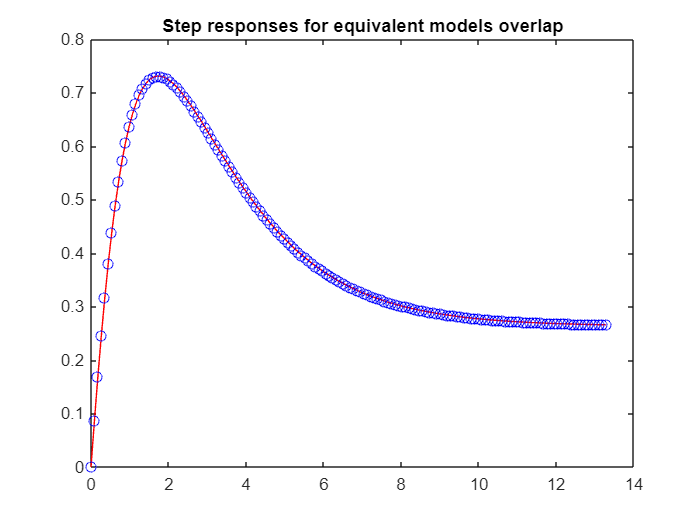

% Compare poles
compare_poles = [eig(A),eig(Ahat)]

% Compare step responses
[y,t]=step(G);
[yhat]=step(Ghat,t);

plot(t,y,'r',t,yhat,'bo');
title('Step responses for equivalent models overlap')


Example 2.2



disp('Example 2.2')
A=[-1 0.1;0.2 -0.5];B=[1;2];C=[1 0];D=0;
G=ss(A,B,C,D);
%Transformation and equivalent model
T=[2 1;0 1]; Ti=inv(T);
Ahat=T*A*Ti; Bhat=T*B;Chat=C*Ti;
Ghat=ss(Ahat,Bhat,Chat,D);

compare_poles =    -1.0372   -1.0372
   -0.4628   -0.4628


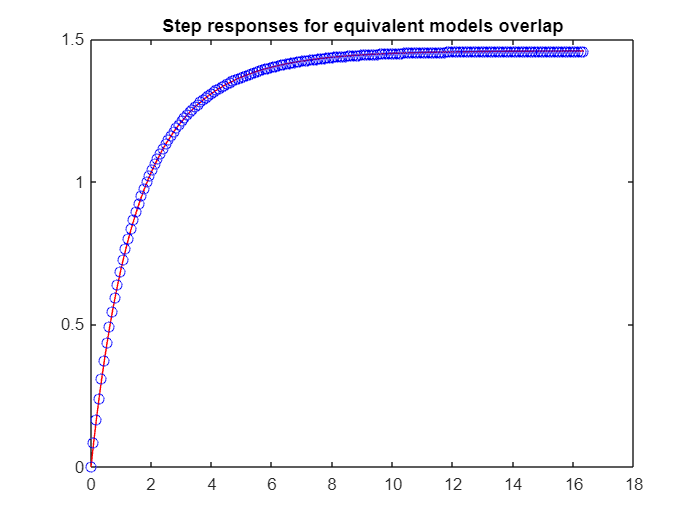

% Compare poles
compare_poles = [eig(A),eig(Ahat)]
% Compare step responses
[y,t]=step(G);
[yhat]=step(Ghat,t);

plot(t,y,'r',t,yhat,'bo');
title('Step responses for equivalent models overlap')

Section 3.1


Example 1


## 3. Useful transformations available with MATLAB

There are an infinite number of possible transformations, but some have an obvious use and thus the following section demonstrates a few of these.

### 3.1 Eigenvalue/vector decomposition

As discussed in the file on phase plane (***phaseplane_behaviour_statespace_control101***) this decomposition both exposes the poles and also directions/behaviour linked to each mode.

Using the eigenvalue/vector decomposition that $A=W\Sigma V$ where $\Sigma \;$is the diagonal matrix of eigenvalues and $W$the matrix of eigenvectors  then:


$$X\left(t\right)=We^{\Sigma t} V\;X\left(0\right)\;\;\;\Rightarrow \;\;\phi \left(t\right)={W\;e}^{\Sigma t} V$$


More to the point, let us consider the state transformation:

$Z=V\;X$, that is the transformation matrix is *T=V*. Now the equivalent model is given as:

$\dot{Z} =\hat{\mathrm{A}} \;Z+\hat{\mathrm{B}} \;U;\;Y=\hat{\mathrm{C}} \;Z+\hat{\mathrm{D}\;} U$ with $\hat{A} =T\;AT^{-1} ;\;\;\;\hat{B} =T\;B;\;\;\hat{C} =CT^{-1}$ and substituting T=V:


$$\hat{A} =V\;AW=\Sigma ;\;\;\;\hat{B} =V\;B;\;\;\hat{C} =C\;W$$


Notably, the new $\hat{A}$ matrix is diagonal and the behaviour of each mode is disentangled which helps with insight, that is:

$Z\left(t\right)=e^{\Sigma t} \;Z\left(0\right)\;$ and $e^{\Sigma t}$  is also diagonal so for each state,  $z_i \left(t\right)=e^{\lambda_i t} z_i \left(0\right)$. This can be demonstrated on the examples below.

disp('Section 3.1')
disp('Example 3.1')
A=[-1 0 0.2;-1 -3 0;0 0.1 -0.5];B=[1;0;-2];C=[1 -1 0]; D=0;
[W,SIGMA]=eig(A);  V=inv(W);
syms t

Ahat =    -3.0040         0         0
         0   -0.9794         0
         0         0   -0.5167


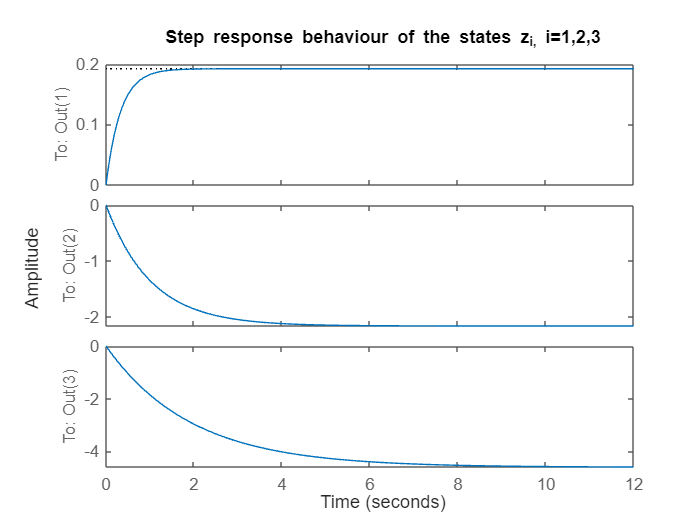


Ahat=V*A*W; Ahat =diag(diag(Ahat))
Bhat=V*B;Chat=C*W;
G1 = ss(Ahat,Bhat,eye(3),zeros(3,1));

step(G1)
title('Step response behaviour of the states z_i, i=1,2,3')

Example 2



disp('Example 3.2')
A=[-1 0.1;0.2 -0.5];B=[1;2];C=[1 0];D=0;
[W,SIGMA]=eig(A);  V=inv(W);

Ahat =    -1.0372         0
         0   -0.4628


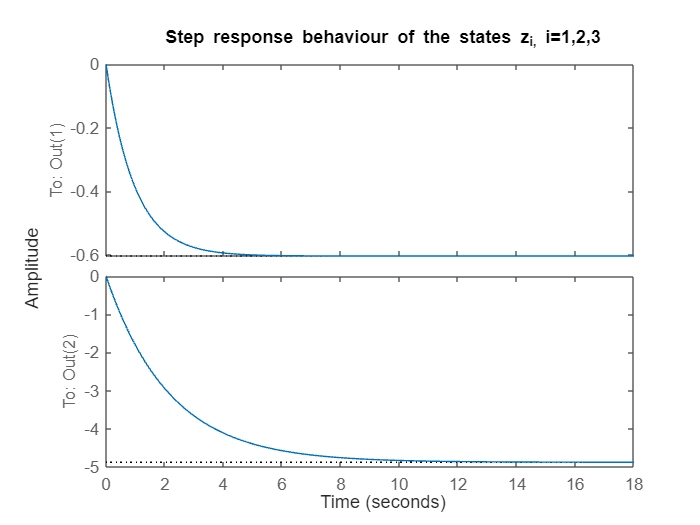


Ahat=V*A*W; Ahat =diag(diag(Ahat))
Bhat=V*B;Chat=C*W;
G2 = ss(Ahat,Bhat,eye(2),zeros(2,1));

step(G2)
title('Step response behaviour of the states z_i, i=1,2')

Section 3.2.1


**Remark**: There also exists something called the modal form which also separates a system into the separate modes (e.g. ***canon(SYS,'modal'), type "help canon" to find out more***); thus it has the same  $\hat{A}$ as above but possibly different $\hat{B} ,\;\hat{C}$. Readers can explore this further should they wish but is not covered here as it also leads one into the issue of non-simple Jordan forms which is beyond the remit of this resource.

### **3.2 Transformations which give canonical forms**

Canonical forms are useful because they guarantee properties useful for feedback and observer design. MATLAB provides tools which define the transformation into a canonical form, assuming that is possible.

- The transformation to controllable canonical form is only possible if the system is controllable.

- The transformation to observable canonical form is only possible if the system is observable.

**Remark**: When beginning from a transfer function and forming an equivalent state space model (***statespace_models_from_tf_control101***), the model should always be controllable and observable (e.g. ***controllability_and_observability_control101***)  and thus one could end up with either form depending upon user choice for the defintions of *A,B,C*. 

MATLAB provides the function "canon.m" which will give the transformation to produce these canonical forms as shown in the code below. See "**doc canon**" and text books for more information.

#### 3.2.1 Controllable companion canonical forms

The equivalent system and associated transformation are given in the code below. Again, the reader is reminded that even canonical forms are not unique due to the possibility for different state and input arrangements. The core point is that the parameters of the characteristic polynomial will appear in a single column or row.

disp('Section 3.2.1')

Canform =
 
  A = 
       x1  x2  x3
   x1   0   0  -4
   x2   1   0   7
   x3   0   1   3
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   5  14
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


T =     1.1571   -0.5143    0.0786
    0.3286   -0.2571    0.1643
   -0.1286    0.0571   -0.0643


A=[0 1 2;-1 3 4;0 2 0];B=[1;0;-2];C=[1 -1 0]; D=0;

Ahat =          0    0.0000   -4.0000
    1.0000    0.0000    7.0000
    0.0000    1.0000    3.0000


G=ss(A,B,C,D);
[Canform,T]=canon(G,'companion')
Ahat = T*A*inv(T)

Example 3.3


### **3.2.2 Transformations for controllable and observable forms**

It is possible to derive explicit formula for the transformations required to produce canonical forms. First assume that the system is controllable and that a controllable formulation exists, and therefore a suitable transformation exists. Form the controllability matrix for both forms:


$$M=\left\lbrack B,A\;B,A^2 B,\ldotp \ldotp \ldotp \right\rbrack ;\;\hat{M} =\left\lbrack \hat{B} ,\hat{A} \hat{B} ,{\hat{A} }^2 \hat{B} ,\ldotp \ldotp \ldotp \right\rbrack$$


The second of these can be expanded as follows.

$\;\hat{M} =\left\lbrack T\;B,T\;A\;B,T\;A^2 B,\ldotp \ldotp \ldotp \right\rbrack =T\;M$ which implies that $T=M^{-1} \hat{M}$

Thus, if we can define the controllable form, then we can easily find the transformation matrix linking that to the original form.

**Remark**: If a model is expressed in transfer function form, the controllable form is easy to derive: ***statespace_models_from_tf_control101 ***.

The examples below show that this definition of *T* does indeed deliver the desired canonical form.

disp('Example 3.3: Equivalence of canonical forms via transfer functions or a transformation')
A=[0 1;0 0]; B=[0;1]; C=[1 0];
Mx=ctrb(A,B);

% Forming canonical SS from a TF
[n,d]=ss2tf(A,B,[1 0],0);
[Ahat,Bhat,Chat,Dhat]=tf2ss(n,d); 

% Forming canonical SS from a transformation matrix T
Mz=ctrb(Ahat,Bhat); 

Comparing results of two methods to find canonical forms


T=Mz*inv(Mx); Ti=inv(T);

method1_method2 =      0     0     0     0
     1     0     1     0


method1_method2 =      1     1
     0     0


disp('Comparing results of two methods to find canonical forms')

method1_method2 =      0     1     0     1


method1_method2=[T*A*Ti,Ahat]
method1_method2=[T*B,Bhat]

Example 3.4: Equivalence of canonical forms via transfer functions or a transformation


method1_method2=[C*Ti,Chat]

disp('Example 3.4: Equivalence of canonical forms via transfer functions or a transformation')
A1=[-5.5 -10.5 -8 -2;1 -0 -0 0;0 1 0 0; 0 0 1 0]; 
B1=[1;0;0;0];

% Forming canonical SS from a TF
C1 = [1 0 0 0];
[n1,d1]=ss2tf(A1,B1,C1,0);
[Ahat1,Bhat1,Chat1,Dhat1]=tf2ss(n1,d1); 

% Forming canonical SS from a transformation matrix T
Mx=ctrb(A1,B1);
Mz=ctrb(Ahat1,Bhat1); 

Comparing results of two methods to find canonical forms


T=Mz*inv(Mx); Ti=inv(T);

method1_method2 =    -5.5000  -10.5000   -8.0000   -2.0000   -5.5000  -10.5000   -8.0000   -2.0000
    1.0000         0         0   -0.0000    1.0000         0         0         0
         0    1.0000         0         0         0    1.0000         0         0
         0         0    1.0000    0.0000         0         0    1.0000         0


method1_method2 =      1     1
     0     0
     0     0
     0     0


disp('Comparing results of two methods to find canonical forms')

method1_method2 =     1.0000    0.0000    0.0000   -0.0000    1.0000         0         0         0


method1_method2=[T*A1*Ti,Ahat1]
method1_method2=[T*B1,Bhat1]
method1_method2=[C1*Ti,Chat1]

**Remark**: *Similarly analogies can be made with the observability matrix. Coding for this is left to student independent study.*


$$O=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
C\;A^2 \\
\vdots 
\end{array}\right\rbrack ;\;\;\hat{O} =\left\lbrack \begin{array}{c}
\hat{C} \\
\hat{C} \hat{A} \\
\hat{C} {\hat{A} }^2 \\
\vdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
C\;T^{-1} \\
C\;{A\;T}^{-1} \\
CA^2 \;T^{-1} \\
\vdots 
\end{array}\right\rbrack =OT^{-1}$$
